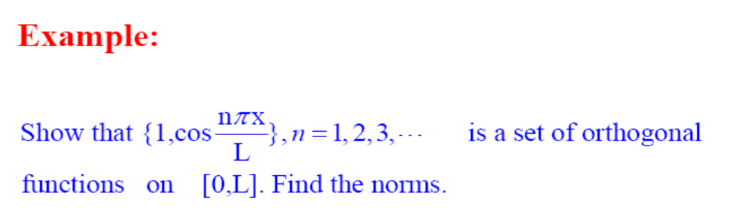

clear;clc;
syms x L;
for n = 1:100
    m = randi(100); 
    fn = cos((n*pi*x)/L);
    fm = cos((m*pi*x)/L);
    eqns = int(fn * fm, x, 0, L);
    if n ~= m && eqns == 0
        fprintf('The functions cos(n*pi*x)/L and cos(m*pi*x)/L are orthogonal on [0, L]')
        break
    else
        fprinf('The functions cos(n*pi*x)/L and cos(m*pi*x)/L not orthogonal on [0, L]')
    end
end

The functions cos(n*pi*x)/L and cos(m*pi*x)/L are orthogonal on [0, L]